# Photo-electric Effect: a Determination of *h* 

Febuary 25th, 2019

PHYS 3605W

Cameron Laedtke 

## Overview

Determine the value of Plank's constant and the work function for a material based on the photo-electric effect. We will find this by analyzing the relationship between emitted wavelength and stopping potential.

## Procedure

Our experiment should show that light is understandable in terms of the absorbtion of indicent photos acting as particles, each with an energy of $E_{\textrm{photon}} =h\nu$  where $\nu$ is the frequency of the light beam, and $h$ is Plank's constant. We expect a linear relationshup between the energy of the absorbed light photon and the maximum energy of the emitted electron. Using this linear relationship, we can experimentally derive the value for Plank's constant. The derivation below shows how we can find Plank's constant by measuring the slope of the linear relationship between wavelength and stopping potential, and the work function by finding the y-intercept of the slope. 

####                     
$$E_{\mathrm{photon}} =V_o e+\omega_o$$
                     
$$E_{\mathrm{photon}} =h\nu =\frac{\mathit{hc}}{\lambda }$$
                      
$$\lambda_{-1} =\frac{V_o e}{\mathit{hc}}+\frac{\omega_o }{\mathit{hc}}$$


Our lab setup consisted of a monochromator, digital voltometer (DVM), power supply, mercury lamp, and incandescent lamp. The basic setup of the monochrometer can be seen in the figure below, where S1 is the input slit, S2 is the exit port, and G is the adjustable diffraction grating. The input slid was initially set to a width of 0.5 mm.

                                          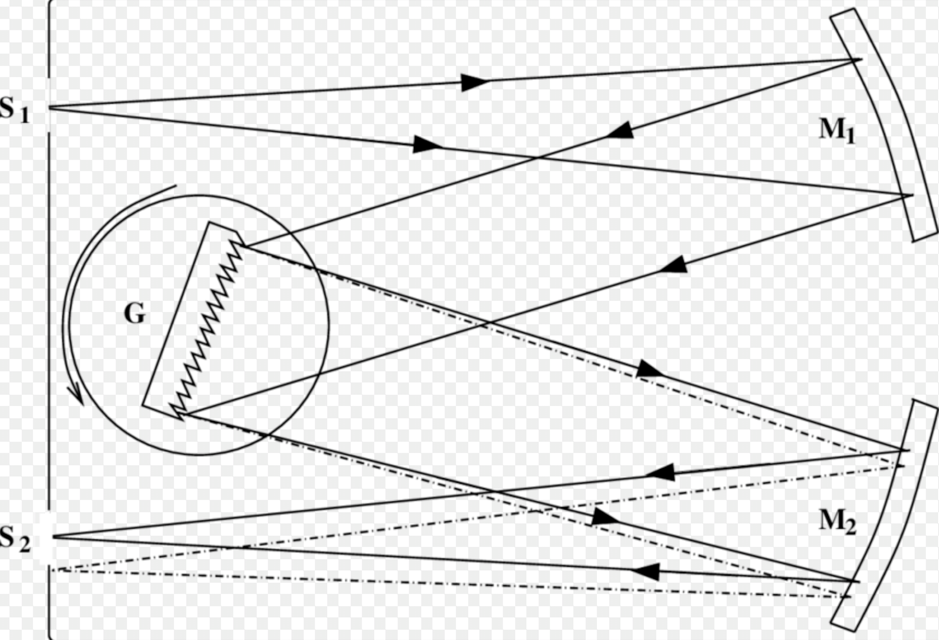

## Calibration of Monochromator

We began our experiment by configuring the monochromator, which consisted of a diffraction grating and mirrors to isolate light of specific, known wavelengths. The angle of the diffraction grating to the incident light beam was adjusted by means of a multi-turn dial. To calibrate the monochromator, we needed to determine the relationship between wavelength and monochromator dial reading. 

A mercury lamp, which provides an emission spectra of several sharp lines of well-known wavelengths, was used for calibration. We removed the photoelectron detector apparatus from the exit port and replaced it with an eyepiece, so we could manually observe the emission spectra. We adjusted the angle of the diffraction grating until we found thin, colored lines. Since the colored lines corresponded to known wavelengths, we recorded various wavelenghts and their corresponding dial readings.

dial_calibration_data = dlmread('lab2data.csv',',',[1, 0, 9, 2]); % turn dial readings
% convert to meters
lambda = dial_calibration_data(:,1).*10^-9; % known wavelengths of mercury spectra (m)

In order to connect any given dial reading with an estimated wavelength, we obtained a linear fit of our dial calibration data and recorded the fit coefficients. The error associated with the dial reading is based off the minimum resolution of the multi-turn dial. We are assuming that the error on the line's wavelength is negligeable.  

dial_reading = dial_calibration_data(:,2); % corresponding dial readings
dial_err = dial_calibration_data(:,3); % dial_err = 0.005 turns for all measurements
[a, b, ea, eb] = myfit(lambda, dial_reading, dial_err)

a = 25.1270

b = -3.7058e+07

ea = 0.0119

eb = 2.4600e+04

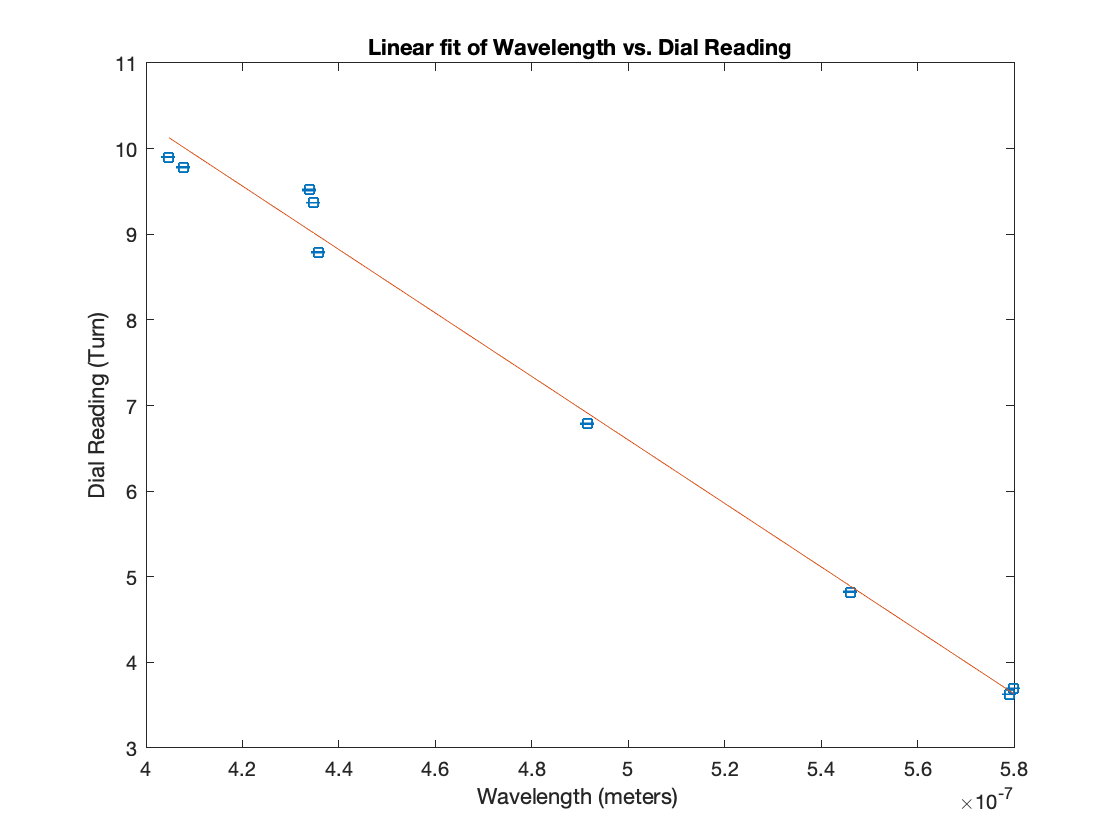

errorbar(lambda, dial_reading, dial_err,'s')
hold on
plot(lambda, lambda.*b + a)
xlabel("Wavelength (meters) ")
ylabel("Dial Reading (Turn)")
title("Linear fit of Wavelength vs. Dial Reading")
hold off

Visually inspecting the plot of wavelength as a function of dial reading, we see that the error bars accomodate for the linear fit line reasonable well. 

## Measuring Stopping Potential as a Function of Incident Wavelength

We replaced the Mercury lamp with an incandescent lamp, which produces a full spectrum of light instead of lines of known wavelength. The DVM was turned on with *Stopping Potential *range set to -2-0 Volts, and current range set to ${10}^{-13} \;\mathrm{Amps}$. On the current amplifier, we adjusted the current calibration knob until it read zero. The incandescent bulb was configured so that a thin bright light was focused on the slit opening. To check our dial calibration, we set the dial to a reading that corresponds to a wavelength of 530 nm, removed the eyepiece, and ensured that a bright green spot came out of the monochromator exit port and onto a piece of white paper. Next, we put the photoelectric detector assembly into to exit port, and connected it to the digital voltometer. 

We set the turn dial to zero, and adjusted the anode potentiual until the current on the ammeter was zero, meaning no photoelectrons were getting from the cathode to the anode. We recorded data on the stopping potential corresponding to turn dial reading, increasing the dial by increments of 0.5 turns from 0 to 10 turns. 

After recording our data for an input slit width of 0.5 mm, we repeated our for an increased slit width of 2.0 mm, meaning a higher intensity of incident light . This allowed us to see if there was any correlation between light intensity and stopping potential.

The two columns of measured stopping potential v_stop_1 and v_stop_2 correspond to input slit width 0.5 mm and 2.0 mm respectively.  Error in the stopping potential is based off of the minimum resolution of the DVM, along with the fact that the voltage level would fluxuate slightly on its own. 

data = dlmread('lab2data.csv',',',[1, 4, 21, 7]);
dial_err = 0.005; % turns
v_stop_1 = data(:,1); % Volts
v_stop_2 = data(:,3); % Volts
sz = size(v_stop_1);
v_stop_err = 0.003.*ones(sz); % Volts
dial = data(:,2); % turns

To examine the relationship between wavelength and stopping potential, we relate dial reading to wavelength using the linear fit found earlier of the form $d=b\lambda +a\;$, where *d* is the dial reading. We can rearange this equation to find $\frac{1}{\lambda }$, since it will be more useful for later calculations.

                     
$$\frac{1}{\lambda }=\frac{b}{d-a}$$
   

We follow the standard error propagation procedure based on variables *d, a, and b *having their own inherent error.  

           
$$\sigma_{\lambda^{-1} } =\sqrt{\sigma_d^2 {\left(\frac{\partial \lambda^{-1} }{\partial d}\right)}^2 +\sigma_a^2 {\left(\frac{\partial \lambda^{-1} }{\partial a}\right)}^2 +\sigma_b^2 {\left(\frac{\partial \lambda^{-1} }{\partial b}\right)}^2 }=\sqrt{\sigma_d^2 {\left(\frac{-b}{{\left(d-a\right)}^2 }\right)}^2 +\sigma_a^2 {\left(\frac{b}{{\left(d-a\right)}^2 }\right)}^2 +\sigma_b^2 {\left(\frac{1}{\left(d-a\right)}\right)}^2 }\;$$


lambda = ((dial-a)./b); %.*(10^-9); % meters
lambda_inv = 1./lambda; % meters^-1
% check equation
lambda_inv_err = sqrt(dial_err.^2.*(-b./(dial-a).^2).^2 + ...
    ea^2.*(b./(dial-a).^2).^2 + eb^2.*(1./(dial-a)).^2); % meters^-1

Next, we plotted stopping potential vs. $\frac{1}{\lambda }$, for our two sets of stopping potential data. 

%hold off
[xneg, xpos, yneg, ypos] = deal(v_stop_err, v_stop_err, lambda_inv_err,...
    lambda_inv_err);
errorbar(v_stop_1, lambda_inv, yneg ,ypos ,xneg ,xpos ,'o', 'DisplayName',...
    '0.5 mm slit')

hold on 
errorbar(v_stop_2, lambda_inv ,yneg ,ypos ,xneg ,xpos, 's', 'DisplayName',...
    '2 mm slit')
[a_v1, b_v1, ea_v1, eb_v1] = myfit(v_stop_1, lambda_inv, lambda_inv_err)

a_v1 = 1.1436e+06

b_v1 = -8.4519e+05

ea_v1 = 952.4869

eb_v1 = 1.2001e+03

[a_v2, b_v2, ea_v2, eb_v2] = myfit(v_stop_2, lambda_inv, lambda_inv_err)

a_v2 = 1.1180e+06

b_v2 = -8.4274e+05

ea_v2 = 1.0040e+03

eb_v2 = 1.2214e+03

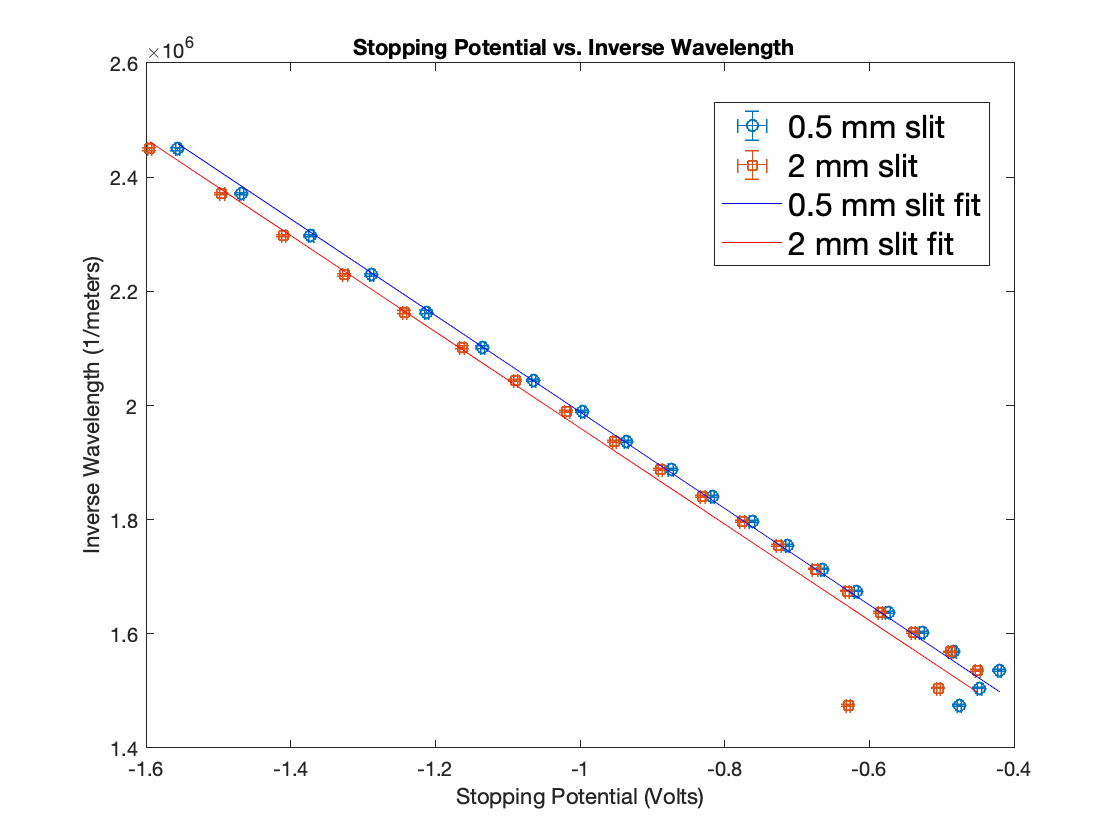


v1_fit_y = v_stop_1.*b_v1+a_v1;
v2_fit_y = v_stop_2.*b_v2+a_v2;

plot(v_stop_1, v1_fit_y, 'b', 'DisplayName', '0.5 mm slit fit')
plot(v_stop_2, v2_fit_y, 'r', 'DisplayName', '2 mm slit fit')

xlabel("Stopping Potential (Volts)")
ylabel("Inverse Wavelength (1/meters)")
title("Stopping Potential vs. Inverse Wavelength  ")

hand = legend('location','northeast');
set(hand, 'fontsize', 16)
set(hand, 'position', [0.66,0.70,0.20,0.16])
hold off

On the bottom right of the plot we can see the datapoints for the lowest three values of anode potential seem to be outliers. An analysis of the chi values for each fit shows them to have unusually high chi values compared to the rest of the points. 

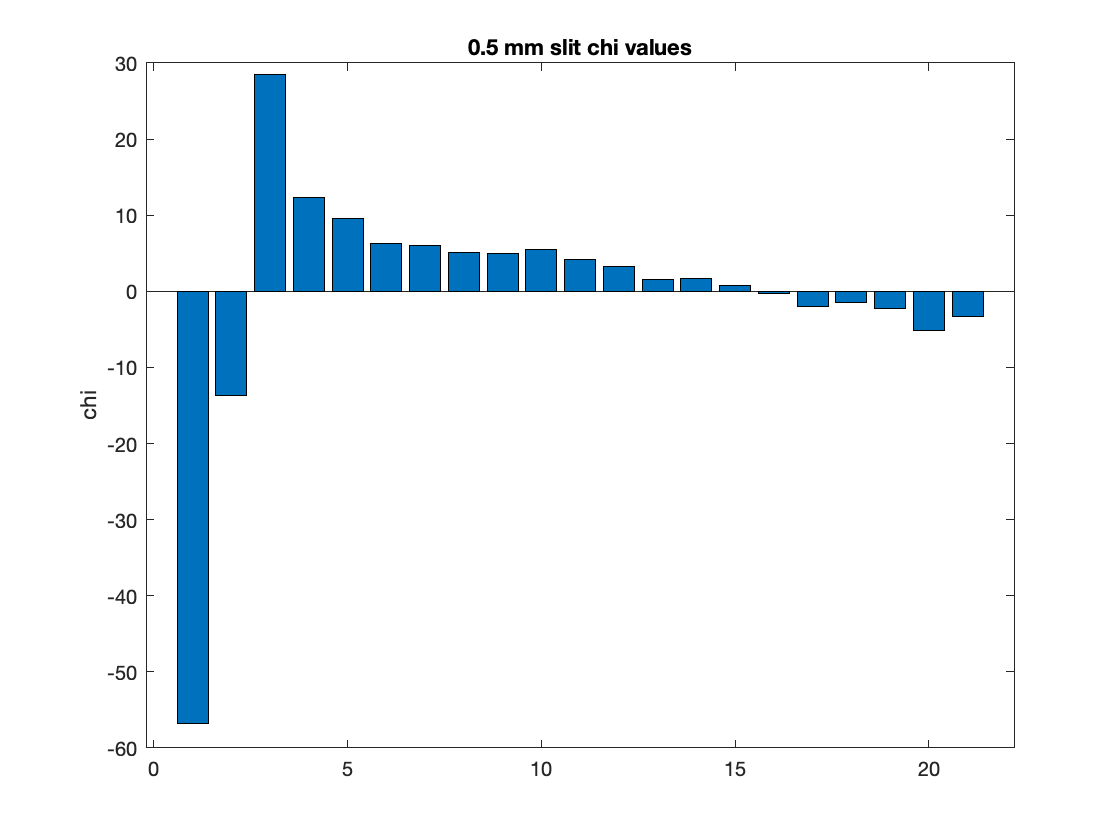

[chi_v1, chi2_v1] = getChi(lambda_inv, v1_fit_y, lambda_inv_err);
[chi_v2, chi2_v2] = getChi(lambda_inv, v2_fit_y, lambda_inv_err);

bar(chi_v1)
title('0.5 mm slit chi values')
ylabel('chi')

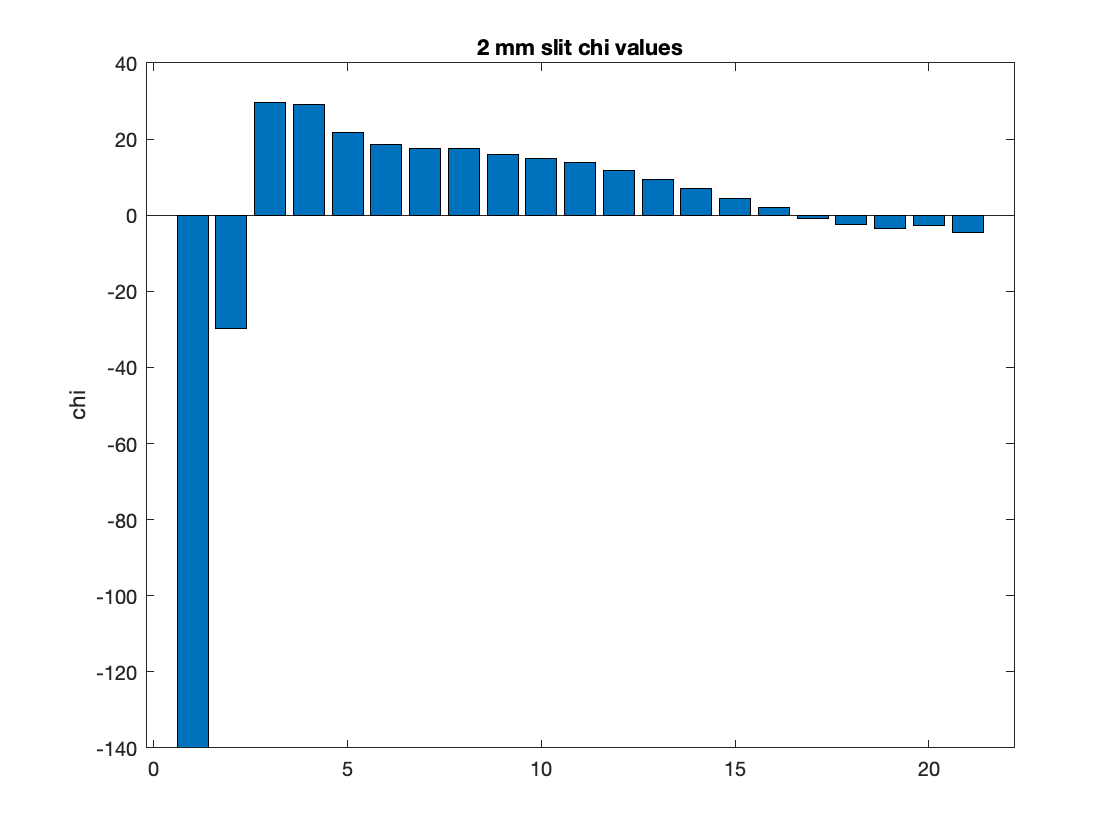

bar(chi_v2)
%plot x vs chi
title('2 mm slit chi values')
ylabel('chi')

It is unlikely that the high chi values on the first three points are due to random error, and must have been caused by a systematic error of some kind. We deleted the first three points from the dataset, and recalculated both linear fits.

dial_fixed = dial(4:end);

lambda_inv_fixed = lambda_inv(4:end, :);
lambda_inv_err_fixed = sqrt(dial_err.^2.*(-b./(dial_fixed-a).^2).^2 + ...
    ea^2.*(b./(dial_fixed-a).^2).^2 + eb^2.*(1./(dial_fixed-a)).^2);
v_stop_1_fixed = v_stop_1(4:end, :);
v_stop_2_fixed = v_stop_2(4:end, :);
sz = size(v_stop_1_fixed);
v_stop_err_fixed = 0.003.*ones(sz);

[xneg, xpos, yneg, ypos] = deal(v_stop_err_fixed, v_stop_err_fixed,...
    lambda_inv_err_fixed, lambda_inv_err_fixed);

errorbar(v_stop_1_fixed, lambda_inv_fixed, yneg, ypos, xneg, xpos,...
    'o', 'DisplayName', '0.5 mm slit')

hold on 
errorbar(v_stop_2_fixed, lambda_inv_fixed, yneg, ypos, xneg, xpos,...
    's', 'DisplayName', '2 mm slit')

[a_v1_fixed, b_v1_fixed, ea_v1_fixed, eb_v1_fixed] = myfit(v_stop_1_fixed, ...
    lambda_inv_fixed, lambda_inv_err_fixed)

a_v1_fixed = 1.1684e+06

b_v1_fixed = -8.2235e+05

ea_v1_fixed = 1.2455e+03

eb_v1_fixed = 1.4227e+03

[a_v2_fixed, b_v2_fixed, ea_v2_fixed, eb_v2_fixed] = myfit(v_stop_2_fixed,...
    lambda_inv_fixed, lambda_inv_err_fixed)

a_v2_fixed = 1.1747e+06

b_v2_fixed = -7.9856e+05

ea_v2_fixed = 1.2352e+03

eb_v2_fixed = 1.3816e+03

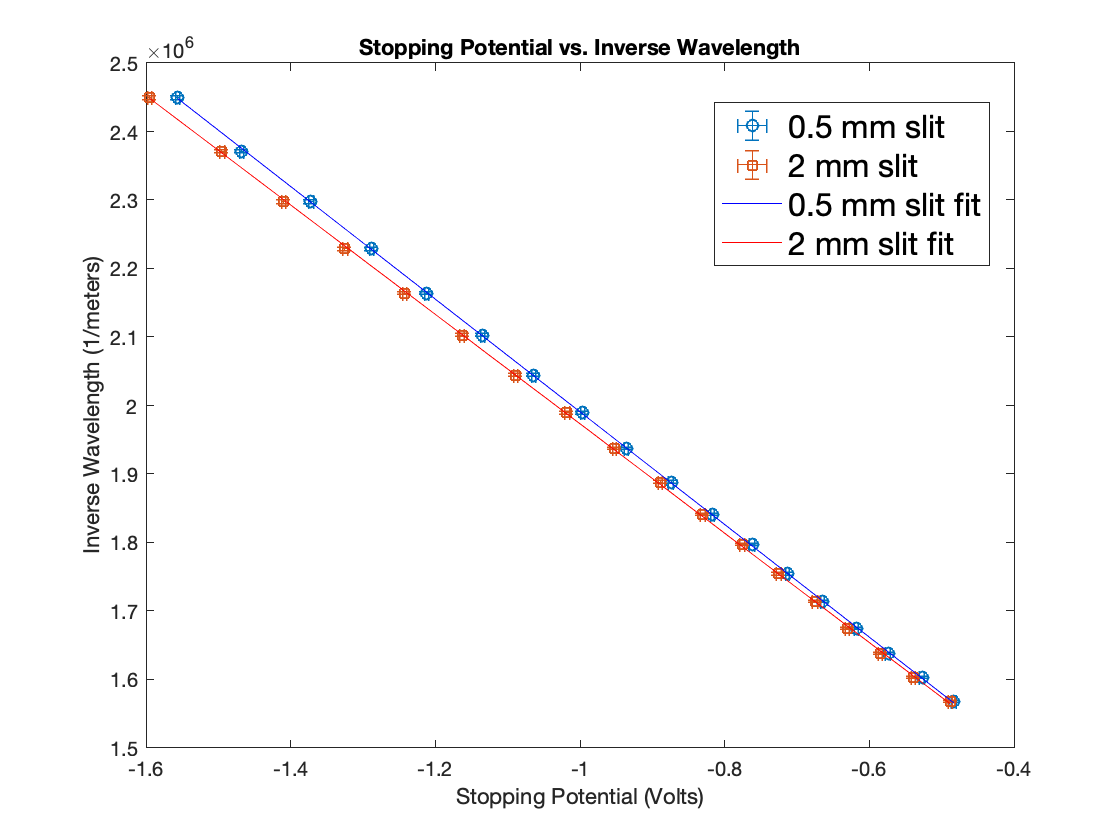


v1_fit_y_fixed = v_stop_1_fixed.*b_v1_fixed+a_v1_fixed;
v2_fit_y_fixed = v_stop_2_fixed.*b_v2_fixed+a_v2_fixed;

plot(v_stop_1_fixed, v1_fit_y_fixed, 'b', 'DisplayName', '0.5 mm slit fit');
plot(v_stop_2_fixed, v2_fit_y_fixed, 'r', 'DisplayName', '2 mm slit fit');

xlabel("Stopping Potential (Volts)")
ylabel("Inverse Wavelength (1/meters)")
title("Stopping Potential vs. Inverse Wavelength")

hand_2 = legend('location','northeast');
set(hand_2, 'fontsize', 16)
set(hand_2, 'position', [0.66,0.70,0.20,0.16])


hold off

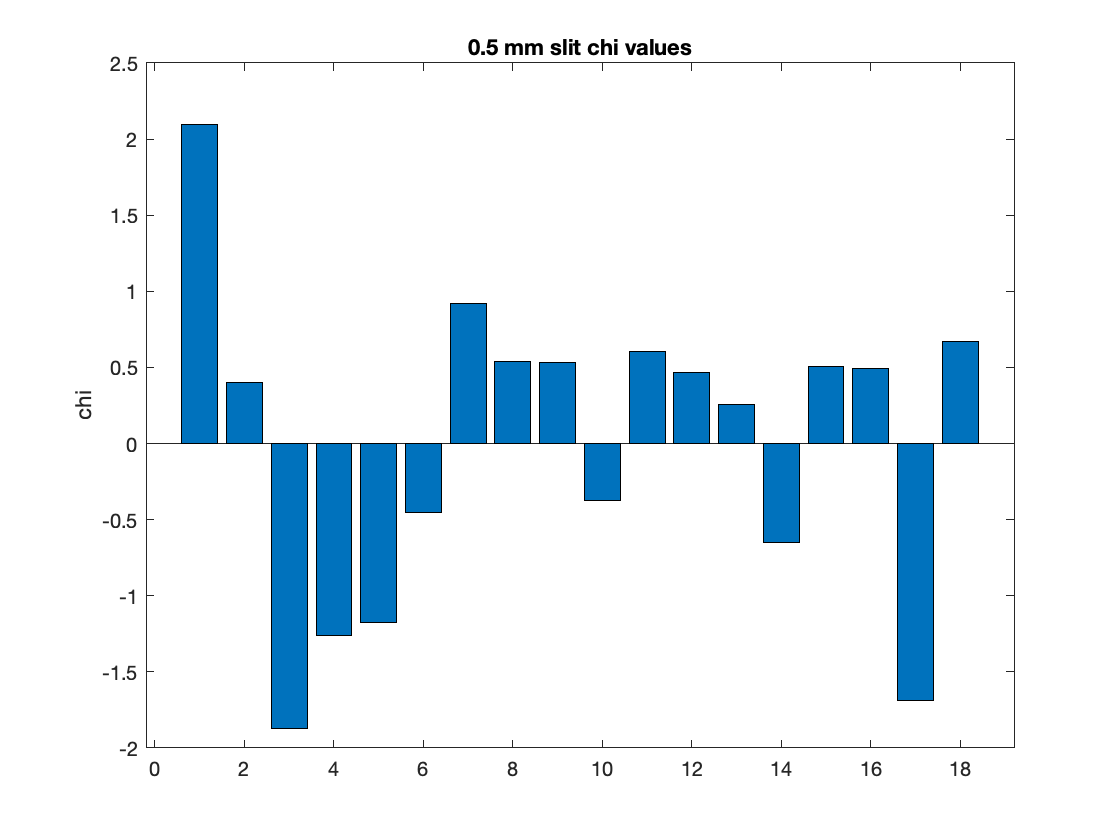

[chi_v1_fixed, chi2_v1_fixed] = getChi(lambda_inv_fixed, v1_fit_y_fixed,...
    lambda_inv_err_fixed);
[chi_v2_fixed, chi2_v2_fixed] = getChi(lambda_inv_fixed, v2_fit_y_fixed,...
    lambda_inv_err_fixed);

bar(chi_v1_fixed)
title('0.5 mm slit chi values')
ylabel('chi')

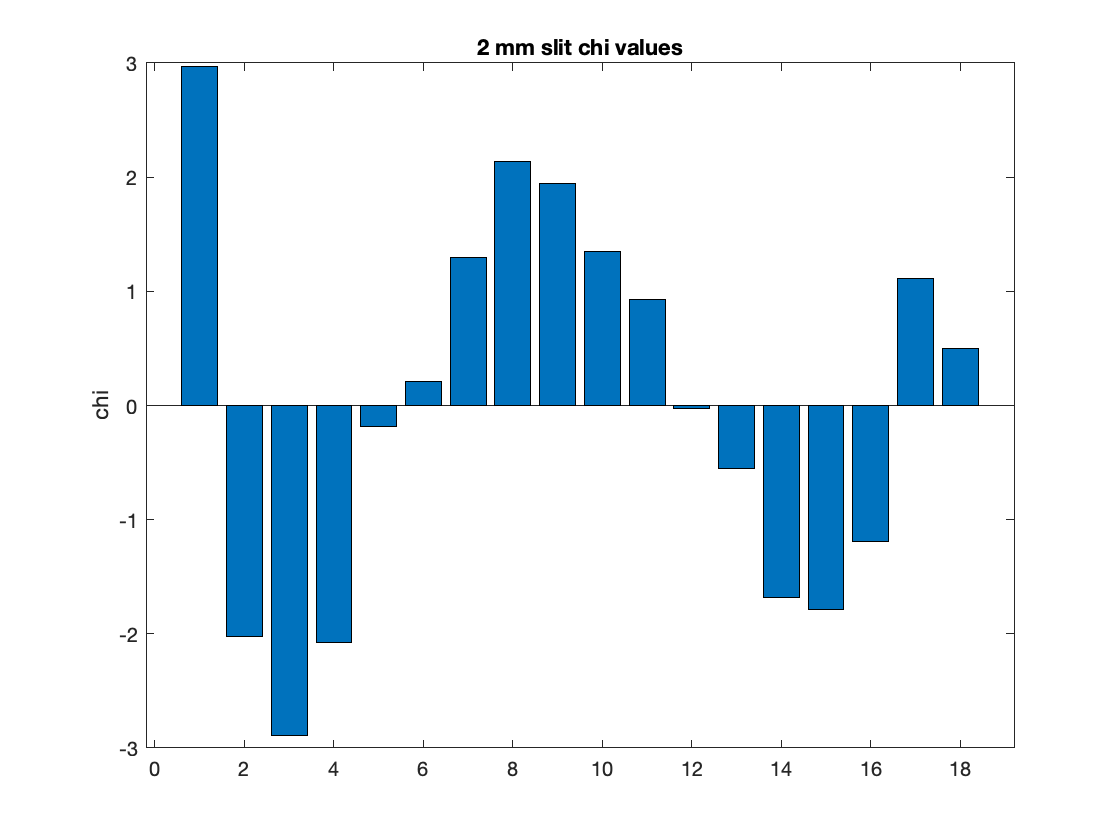

bar(chi_v2_fixed)
%plot x vs chi
title('2 mm slit chi values')
ylabel('chi')

The fact that the two linear fits are almost identical shows how the intensity of incident light has no impact on stopping potential. Relating the coefficients of our linear fit functions of the form *y = bx + a *to the equation below, we can determine our expetimental values for Plank's constant *h*, and work function $\omega_o$. Error propagation equations for *h *and $\omega_o$ are listed below as well.

####            
$$\lambda^{-1} =\frac{V_o e}{\textrm{hc}}+\frac{\omega_o }{\textrm{hc}}\;\;$$
              
$$h=\frac{e}{\textrm{bc}}\;$$
                 
$$\omega_o =\textrm{ahc}\;\;$$


####             
$$\sigma_h =\sqrt{\sigma_b^2 {\left(\frac{\partial h}{\partial b}\right)}^2 }=\sqrt{\sigma_b^2 {\left(\frac{-e}{b^2 c}\right)}^2 }\;\;=\frac{-\sigma_b e}{b^2 c}$$
           
$$\sigma_{\omega_o } =\textrm{hc}\sigma_a \;\;\;$$


  Now we can calculate our values for *h *and $\omega_o$ for the two sets of data, and combine them for a weighted average. 

e = -1.602*10^-19; % charge of an electron (coulombs)
c = 2.998*10^8; % speed of light (meters/second)

h1 = ((b_v1_fixed*c)/e)^-1

h1 = 6.4979e-34


h1_err = (-eb_v1_fixed*e)/(b_v1_fixed^2*c)

h1_err = 1.1242e-36

%h1_err = sqrt(eb_v1_fixed^2*(-e/(b_v1_fixed^2*c))^2);

h2 = ((b_v2_fixed*c)/e)^-1

h2 = 6.6915e-34

h2_err = sqrt(eb_v2_fixed^2*(-e/(b_v2_fixed^2*c))^2)

h2_err = 1.1577e-36

%w1 = -a_v1_fixed*h1*c
w1 = -a_v1_fixed*h1*c/e

w1 = 1.4208

w1_err = h1*c*ea_v1_fixed/e

w1_err = -0.0015

%w2 = -a_v2_fixed*h2*c
w2 = -a_v2_fixed*h2*c/e

w2 = 1.4711

w2_err = h2*c*ea_v2_fixed/e

w2_err = -0.0015


h_obs = [h1, h2];
h_errs = [h1_err, h2_err];
h_sum1 = sum(h_obs./h_errs.^2);
h_sum2 = sum(1./h_errs.^2);
h_weighted_avg = h_sum1/h_sum2

h_weighted_avg = 6.5919e-34

h_weighted_avg_err = sqrt(1/h_sum2)

h_weighted_avg_err = 8.0650e-37


w_obs = [w1, w2];
w_errs = [w1_err, w2_err];
w_sum1 = sum(w_obs./w_errs.^2);
w_sum2 = sum(1./w_errs.^2);
w_weighted_avg = w_sum1/w_sum2

w_weighted_avg = 1.4454

w_weighted_avg_err = sqrt(1/w_sum2)

w_weighted_avg_err = 0.0011

Experimental: $h=6\ldotp 63*{10}^{-34\;} \;\pm 1*{10}^{-45} \;\mathrm{Js}$

Actual: $h=6\ldotp 626*{10}^{-34\;} \textrm{Js}$

Work function:  $\omega_o =1\ldotp 46\pm 2*10^{-31} \;\;\mathrm{eV}$

My experimental calculation of *h* is *very* close to its actual value of *h* = 6.626*10^-34 Js. However, the uncertainty I obtained for both *h * and $\omega_o$ were both unrealistically small more then ten orders of magnitude smaller than any realistic experimental error. This indicates either a likely miscalculation of one of our error propagation equations, or failure to take additional sources of error into account when setting up equations for linear fit. 

My obtained value for the work function is closest to that of the metal Cesium ($\omega_o =2\ldotp 1$). 

function [a, b, ea, eb] = myfit(x,y,ey)
  sx = sum(x ./ (ey .^ 2) );
  sy = sum(y ./ (ey .^ 2) );
  sxx = sum((x .* x) ./ (ey .^ 2) );
  sxy = sum((x .* y) ./ (ey .^ 2) );
  s = sum(1 ./ (ey .^ 2) );
  delta=sxx*s-sx*sx;
  a=(sxx*sy-sx*sxy)/delta;
  ea=sqrt(sxx/delta);
  b=(s*sxy-sx*sy)/delta;
  eb=sqrt(s/delta);
end


function [chi, chi2] = getChi(y, fit_y, y_err)
   chi = (y - fit_y)./(y_err);
   chi2 = chi.^2;
end